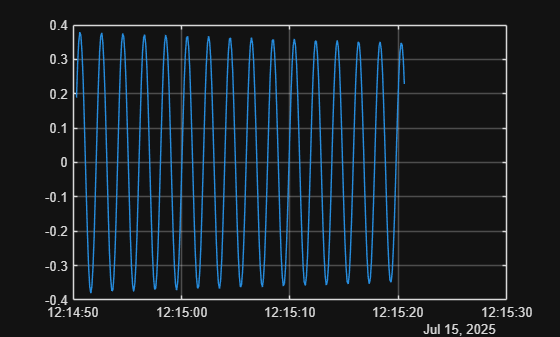

clear
clc
% tau calculations for the platofrm
file_platform = "C:\Users\Jordan Baylos\Desktop\eVTOL Trifilar\DUST 4 Trifiler MOI Calculations\DUST 4 Trifiler Raw Data\Sensor on Axis\TrifilarTestData_PhoneOnAxis_7-15-25 (4).mat";
load(file_platform)
x_platform =  AngularVelocity.Timestamp;
y_platform = AngularVelocity.Z;
plot(x_platform,y_platform)
grid on

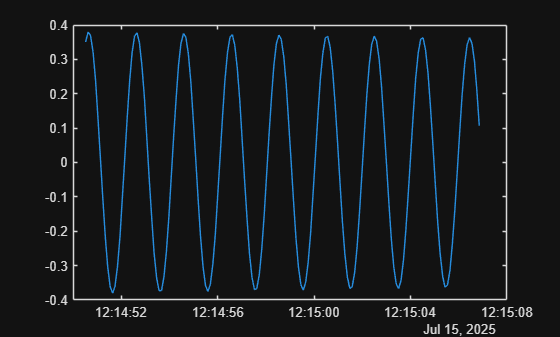

peaks_platform = findpeaks(y_platform);
minTime = 10;
maxTime = 550;
maxIdx = round(maxTime*length(x_platform)/1000);
minIdx = round(minTime*length(x_platform)/1000);
plot(x_platform(minIdx:maxIdx),y_platform(minIdx:maxIdx))

% Adjust this value based off the data you see on the graph
peak_threshold_platform = 0.2;
[pks,locs] = findpeaks(y_platform(minIdx:maxIdx),'MinPeakHeight',peak_threshold_platform);
peak_times_platform = x_platform(locs);
period_platform = seconds(diff(peak_times_platform));
mean_period_platform = mean(period_platform) %this is the tau of the platform

mean_period_platform = 1.9773

frequency_platform = 1./period_platform;
mean_frequency_platform = mean(frequency_platform)

mean_frequency_platform = 0.5061

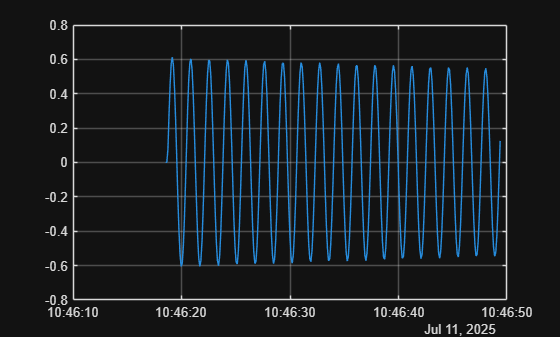

% tau calculations for the component
file_component = "C:\Users\Jordan Baylos\Desktop\eVTOL Trifilar\DUST 4 Trifiler MOI Calculations\DUST 4 Trifiler Raw Data\Sensor on Axis\Trifilar_Battery_ValidationTest_07-11-25.mat";
load(file_component)
x_component = AngularVelocity.Timestamp;
y_component = AngularVelocity.Z;
plot(x_component, y_component);
grid on;

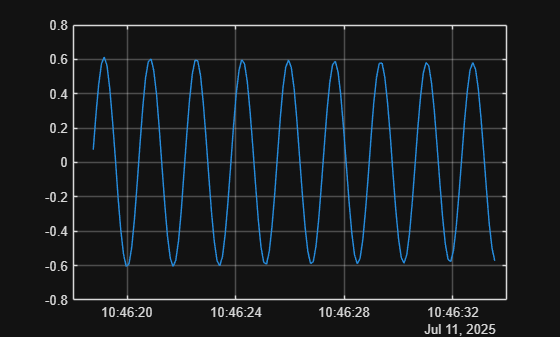

peaks_component = findpeaks(y_component);
minTime = 10;
maxTime = 490;
maxIdx = round(maxTime*length(x_component)/1000);
minIdx = round(minTime*length(x_component)/1000);
plot(x_component(minIdx:maxIdx),y_component(minIdx:maxIdx))
grid on

% Adjust this value based off the data you see on the graph
peak_threshold_component = 0.4;
[pks_component, locs_component] = findpeaks(y_component(minIdx:maxIdx), 'MinPeakHeight', peak_threshold_component);
peak_times_component = x_component(locs_component);
period_component = seconds(diff(peak_times_component));
mean_period_component = mean(period_component) % this is the tau of the component

mean_period_component = 1.6985

frequency_component = 1./period_component;
mean_frequency_component = mean(frequency_component)

mean_frequency_component = 0.5892


R = 29.5; %in, this is the distance from the cables to the cg of the rotating platform
g = 386.4; %in/s^2
tau_platform = mean_period_platform;
tau_component = mean_period_component;
L = (128); %in
Mass_of_component = 5.36; %pounds
Mass_of_platform = (15) + 0.375; %pound, weight of the platform + the mass of the phone

% Moment of Inertia Calculations
[I_platform] = Ixyz_platform(R, g, tau_platform, L, Mass_of_platform)

I_platform = 3.9999e+03

[I_component] = Ixyz_Trifilar(R, g, tau_component, L,Mass_of_component ,Mass_of_platform,I_platform) %pound-in^2

I_component = -19.3235

% function for the moment of inertia of the platform
function [I_platform] = Ixyz_platform(R, g, tau_platform, L, Mass_of_platform)
I_platform = (R^2*g*tau_platform^2)/(4*pi^2*L)*(Mass_of_platform);
end

% function for the moment of inertia calculations of the component
function [I_component] = Ixyz_Trifilar(R, g, tau_component, L, Mass_of_component,Mass_of_platform,I_platform)
I_component = (R^2*g*tau_component^2)/(4*pi^2*L)*(Mass_of_component + Mass_of_platform) - I_platform;
end